## Time-domain analysis

Say, we want not only to examine circuits in the s-domain, but also in the more intuitive time-domain, as is so often the case. ELABorate has built-in functionality for this. Let's start by loading in a simple 1st-order-series-rc-circuit, otherwise known as a low-pass fitler. This has an AC-source.

circuit = Circuit('circuits/ac_source.txt');
circuit.list

ans =     'Vs 1 0 AC 10-10*exp(-5000*t)
     R1 1 2 10000
     C1 2 0 0.00000001
     '


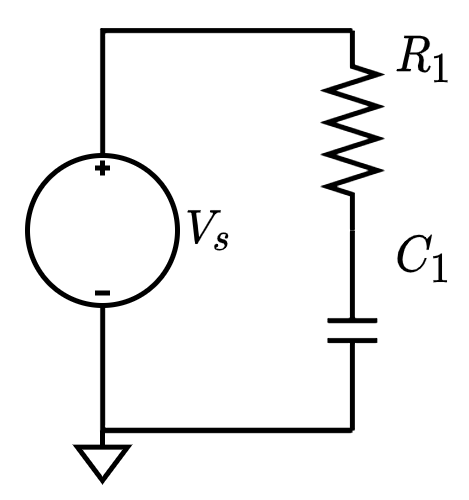

We analyze it as usual to obtain the circuit equations. If evaluate detects that the circuit has not been analyzed, it does it automatically.

ELAB.evaluate(circuit)

Symbolic analysis successful (0.302353 sec).

Numerical evaluation successful (0.278234 sec).


In this case, we would like to know the voltage across the capacitor. `Evaluate` has saved the results in the circuit object.

sd = circuit.numerical_element_voltages(2)

$$sd = v_{\mathrm{C1}}=-\frac{\frac{10}{s+5000}-\frac{10}{s}}{\frac{s}{10000}+1}$$

We transmute the result into the time-domain. We only need the right-hand-side.

td = ELAB.sd2td(rhs(sd))

$$td = 10\,{\mathrm{e}}^{-10000\,t}-20\,{\mathrm{e}}^{-5000\,t}+10$$

We plot the input voltage (blue) and the voltage across the capacitor (orange).

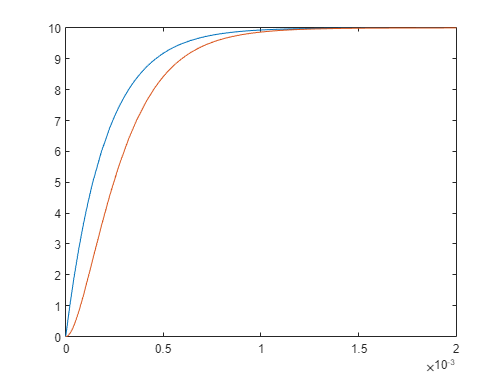

fplot(circuit.Indep_VSs(1).voltage, [0,0.002]); hold on;
fplot(td, [0,0.002]); hold off;